## **TASK 1 (a)**

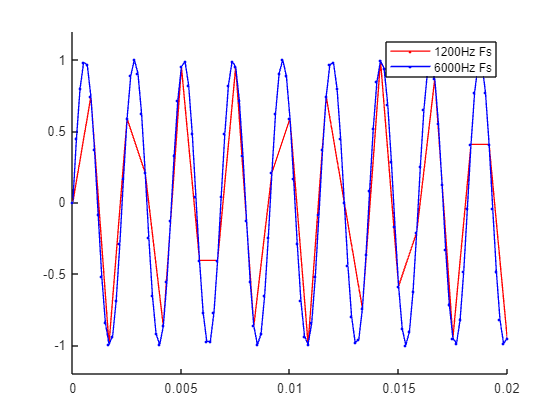

f_s1 = 1200; f_s2 = 6000; f = 440; duration = 2;
t = 0:1/(100*f):duration; x = sin(2*pi*f*t);
t_s1 = 0:1/f_s1:duration; t_s2 = 0:1/f_s2:duration;
x_s1 = sin(2*pi*f*t_s1); x_s2 = sin(2*pi*f*t_s2);
figure
hold on;
plot(t_s1, x_s1, 'r.-', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
plot(t_s2, x_s2, 'b.-', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
legend ('1200Hz Fs', '6000Hz Fs');
hold off;

sound(x_s1, f_s1);
 

sound(x_s2, f_s2); 
 

## **TASK 1 (b)**

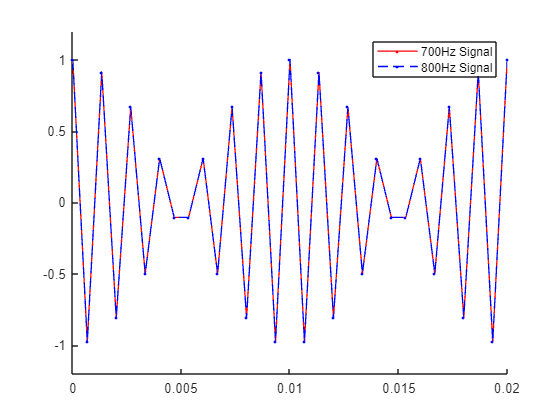

f_s = 1500; duration = 2; t = 0:1/(f_s):duration;
x1 = cos(2*pi*700*t); x2 = cos(2*pi*800*t);
figure
hold on;
plot(t, x1, 'r.-', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
plot(t, x2, 'b.--', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
legend('700Hz Signal','800Hz Signal')
hold off;

700Hz signal

sound(x1, f_s); 
 

800Hz signal

sound(x2, f_s);
 

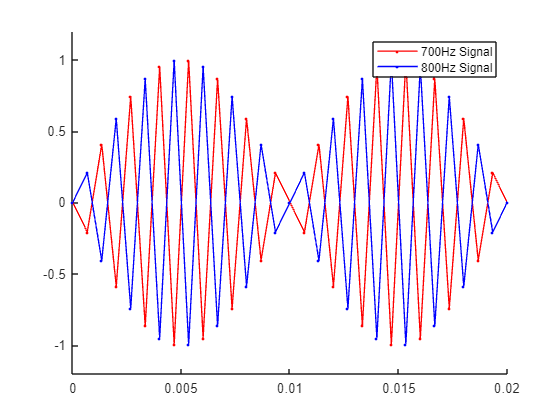

x1_new = cos(2*pi*700*t + pi/2); x2_new = cos(2*pi*800*t + pi/2);
figure
hold on;
plot(t, x1_new, 'r.-', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
plot(t, x2_new, 'b.-', 'LineWidth', 1); ylim([-1.2 1.2]); xlim([0 0.02]);
legend('700Hz Signal','800Hz Signal')
hold off;

700Hz signal with pi/2 phase shift

sound(x1_new, f_s); 
 

800Hz signal with pi/2 phase shift

sound(x2_new, f_s);
 

## **TASK 1 (c)**

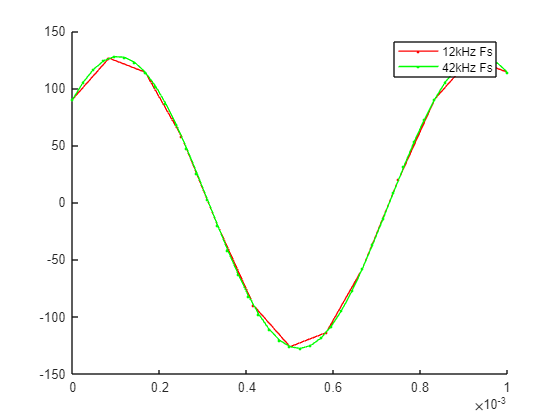

A = 128; f0 = 1200; theta = pi/4; 
fs_12k = 12000; fs_42k = 42000;
t_12k = 0:1/fs_12k:duration; t_42k = 0:1/fs_42k:duration;

x_s12k = A*sin(2*pi*f0*t_12k + theta); x_s42k = A*sin(2*pi*f0*t_42k + theta);
figure
hold on;
plot(t_12k, x_s12k, 'r.-', 'LineWidth', 1); xlim([0 0.001]);
plot(t_42k, x_s42k, 'g.-', 'LineWidth', 1); xlim([0 0.001]);
legend ('12kHz Fs', '42kHz Fs');
hold off;

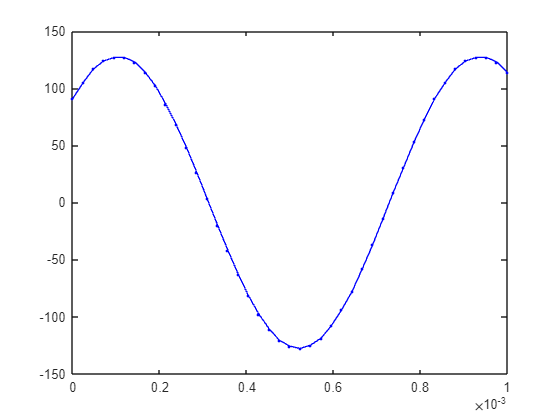

conv_8bit = int8(x_s42k);
figure
plot(t_42k, conv_8bit, 'b.-', 'LineWidth', 1); xlim([0 0.001]);

## **TASK 2 (a)**

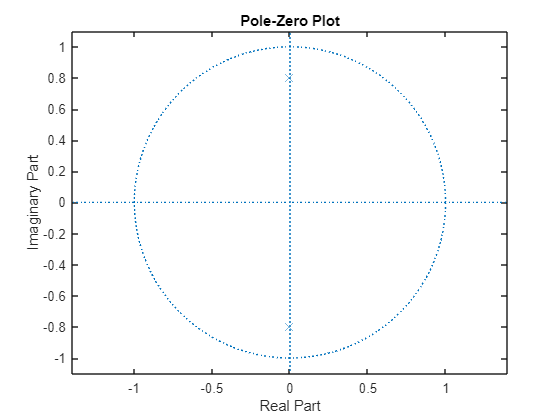

% 1) 0.36y[n] = x[n-2]
num1 = [0 0 1]; den1 = [1 0 0.64];
zplane(num1, den1)

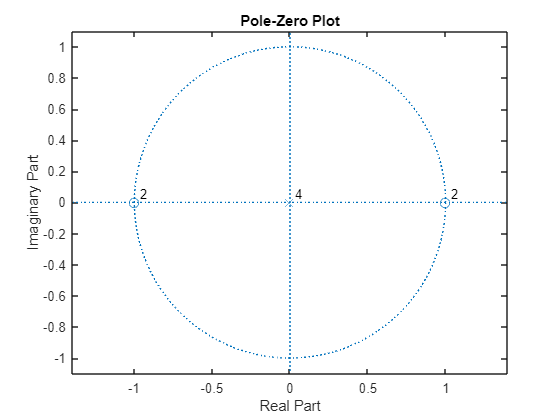

% 2) y[n] = x[n] - 2x[n-2] + x[n-4]
num2 = [1 0 -2 0 1]; den2 = [1];
zplane(num2,den2)

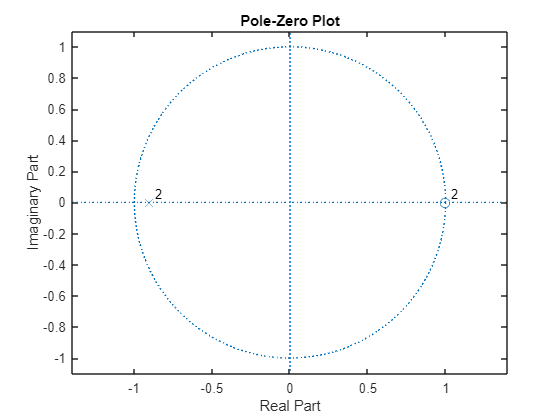

% 3) 𝑦[n] + 1.8𝑦[𝑛 − 1] + 0.81𝑦[𝑛 − 2] = 𝑥[𝑛] − 2𝑥[𝑛 − 1] + 𝑥[𝑛 − 2]
num3 = [1, -2, 1]; den3 = [1, 1.8, 0.81];
zplane(num3,den3)

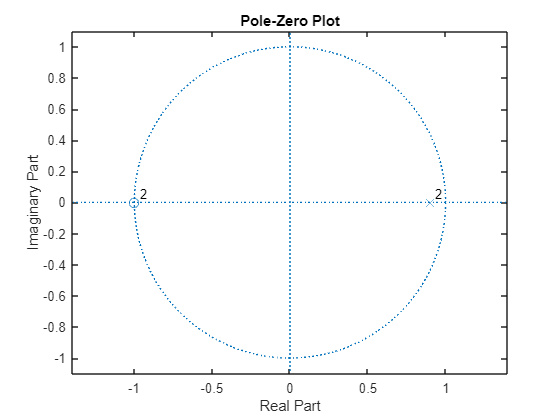

% 4) 𝑦[𝑛] − 1.8𝑦[𝑛 − 1] + 0.81𝑦[𝑛 − 2] = 𝑥[𝑛] + 2𝑥[𝑛 − 1] + 𝑥[𝑛 − 2]
num4 = [1, 2, 1]; den4 = [1, -1.8, 0.81];
zplane(num4,den4)

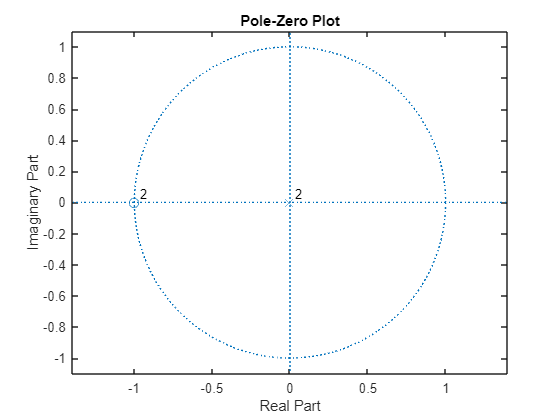

% 5) h[n] = [0.25, 0.5, 0.25]
num5 = [0.25, 0.5, 0.25];
zplane(num5,1)

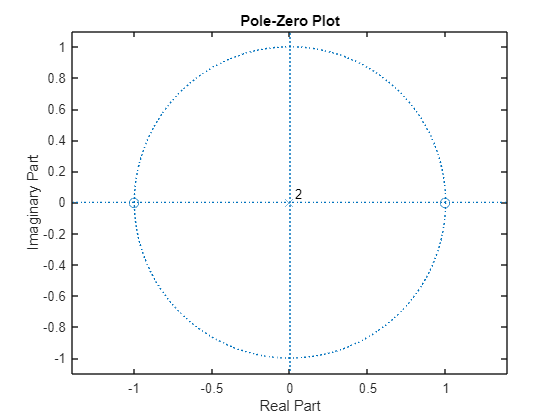

% 6) h[n] = [1, 0, -1]
num6 = [1, 0, -1];
zplane(num6,1)

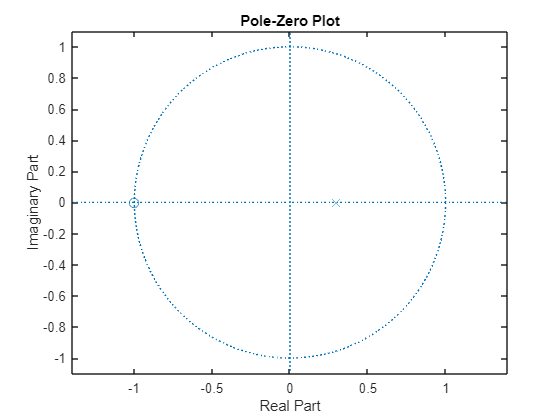

% 7) H(z) = (0.3 + 0.3z–1)/(1 – 0.3z–1)
num7 = [0.3 0.3]; den7  = [1 -0.3];
zplane(num7,den7)

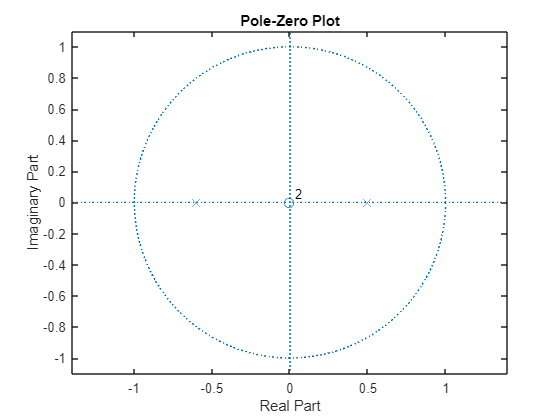

% 8) H(z) = 1/(1 + 0.1z-1 – 0.3z-2)
den8 = [1 0.1 -0.3];
zplane(1, den8)

## **TASK 2 (b)**

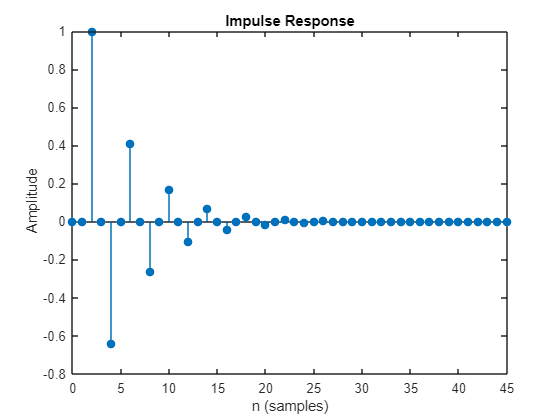

impz(num1, den1)

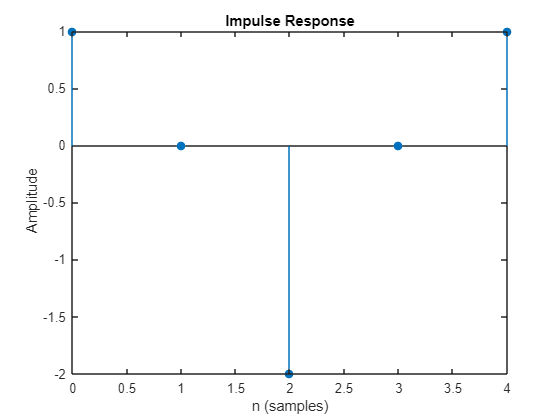

impz(num2,den2)

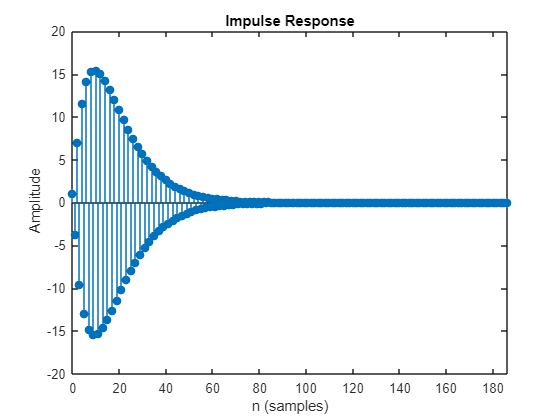

impz(num3, den3)

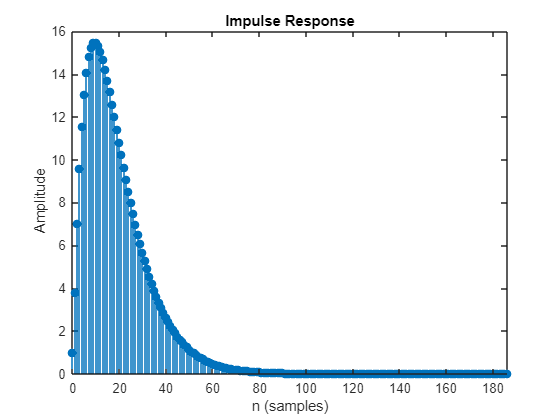

impz(num4, den4)

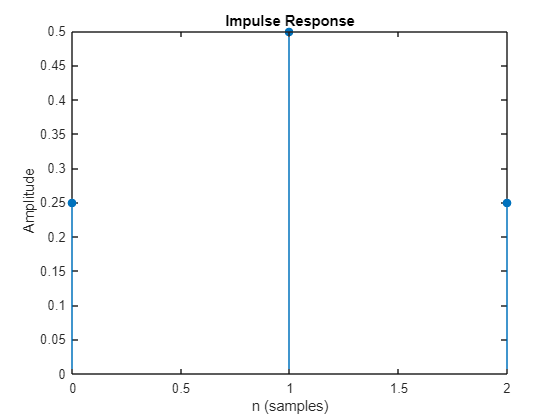

impz(num5,1)

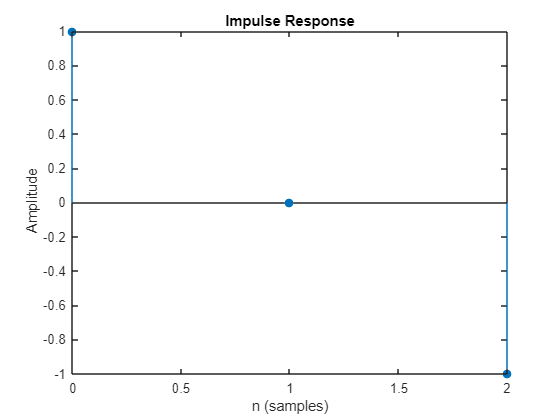

impz(num6,1)

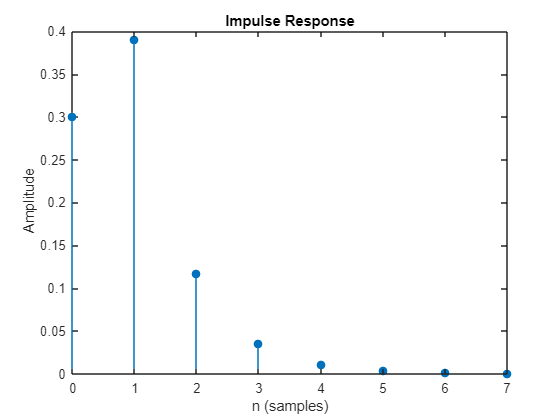

impz(num7,den7)

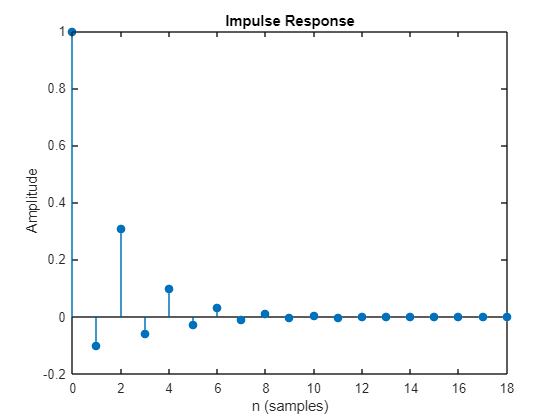

impz(1,den8)

## **TASK 2 (c)**

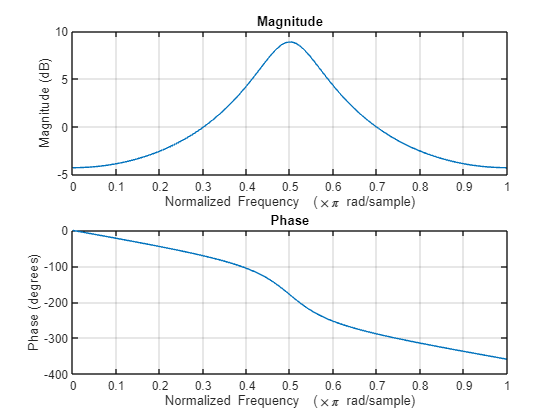

freqz(num1, den1)

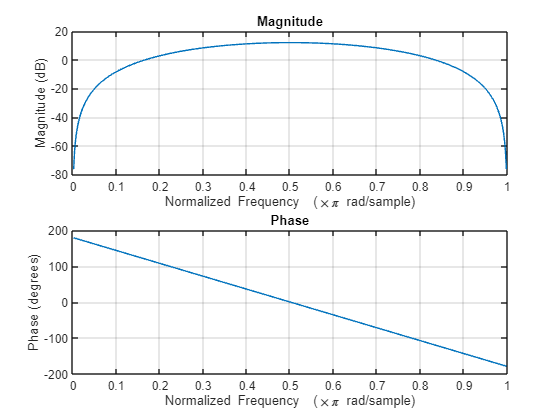

freqz(num2,den2)

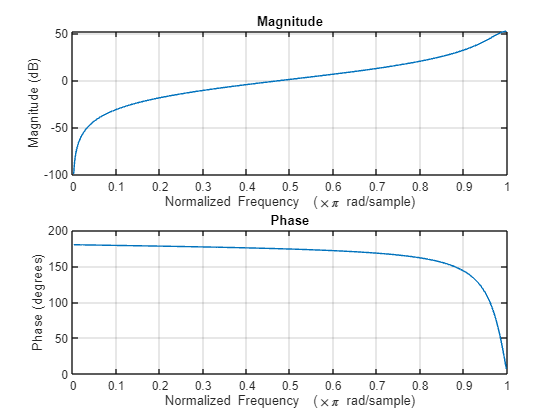

freqz(num3, den3)

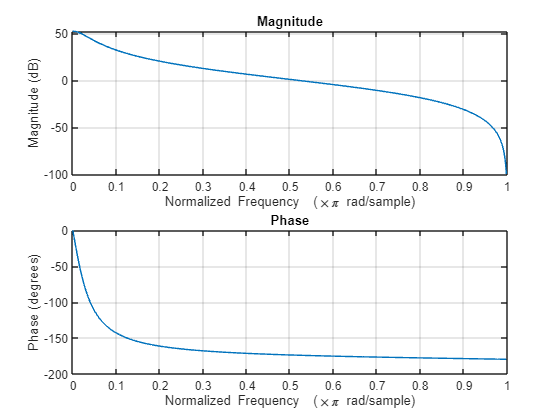

freqz(num4, den4)

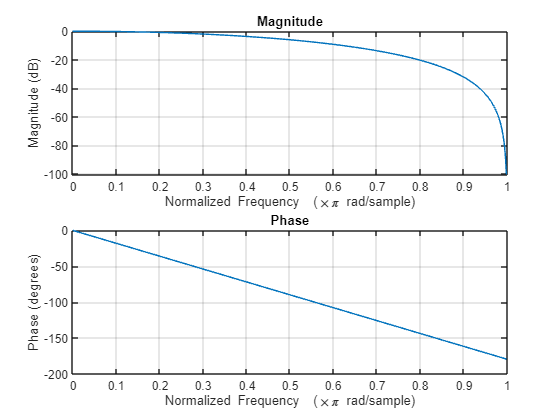

freqz(num5,1)

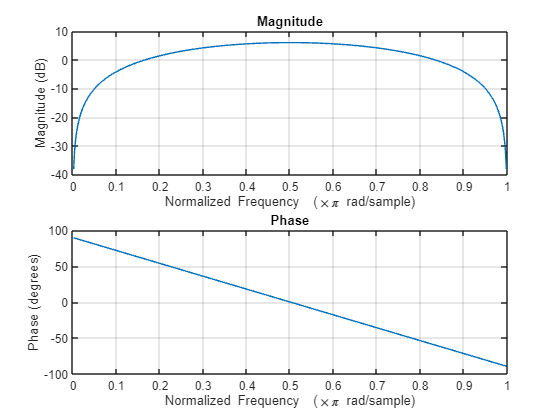

freqz(num6,1)

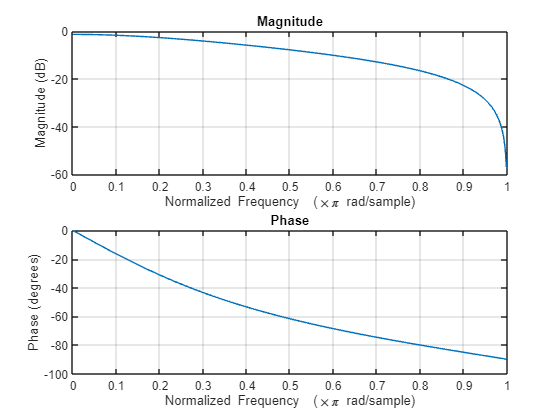

freqz(num7,den7)

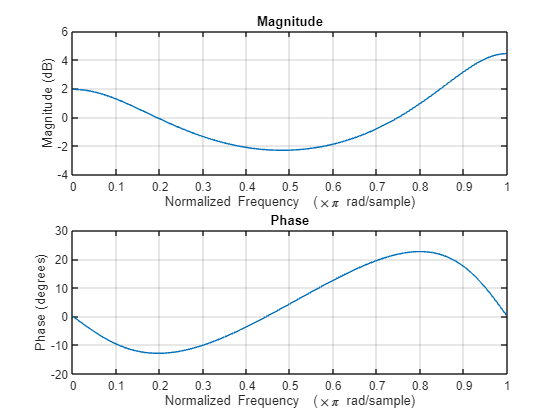

freqz(1,den8)

## **TASK 2 (d)**

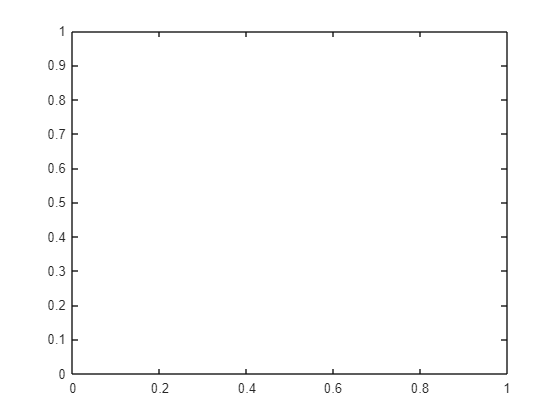

n = 0:100; 
x = 0.9.^n .* sin(n) .* (n >= 0); 

imp_1 = conv(num1, 1 ./ den1);
conv_1 = conv(x, imp_1, 'same');
stem(n,conv_1)

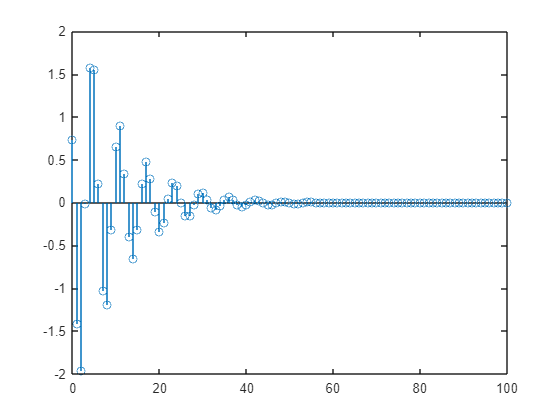

imp_2 = conv(num2, 1 ./ den2);
conv_2 = conv(x, imp_2, 'same');
stem(n,conv_2)

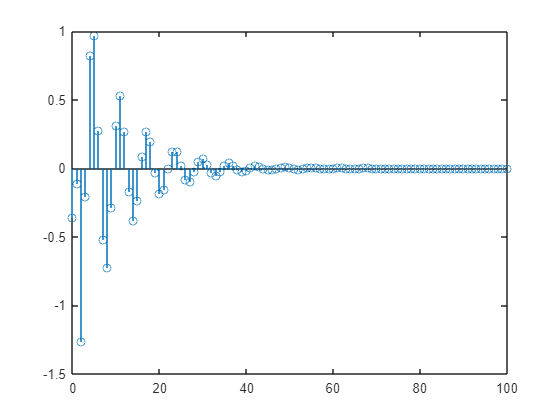

imp_3 = conv(num3, 1 ./ den3);
conv_3 = conv(x, imp_3, 'same');
stem(n,conv_3)

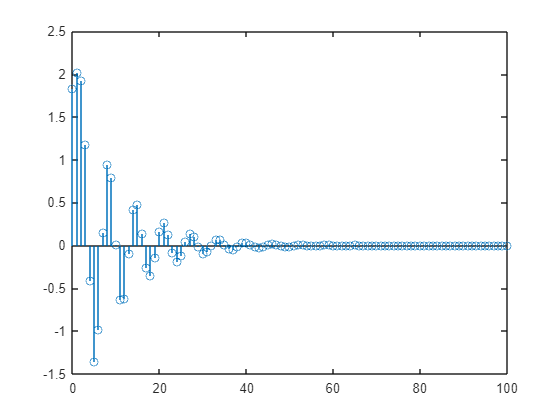

imp_4 = conv(num4, 1 ./ den4);
conv_4 = conv(x, imp_4, 'same');
stem(n,conv_4)

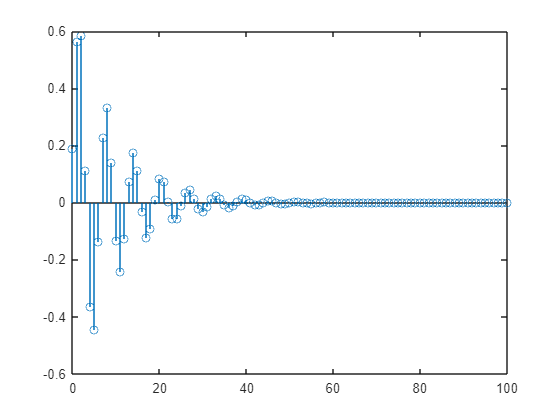

imp_5 = conv(num5, 1 ./ 1);
conv_5 = conv(x, imp_5, 'same');
stem(n,conv_5)

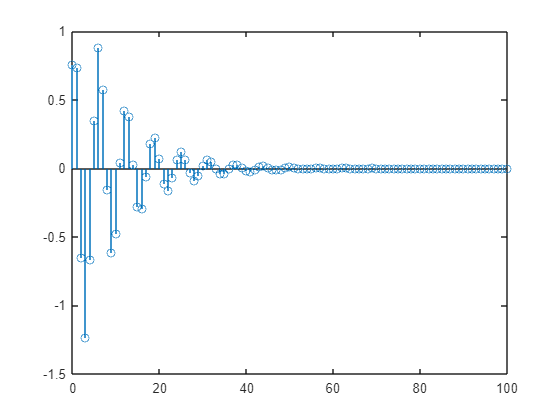

imp_6 = conv(num6, 1 ./ 1);
conv_6 = conv(x, imp_6, 'same');
stem(n,conv_6)

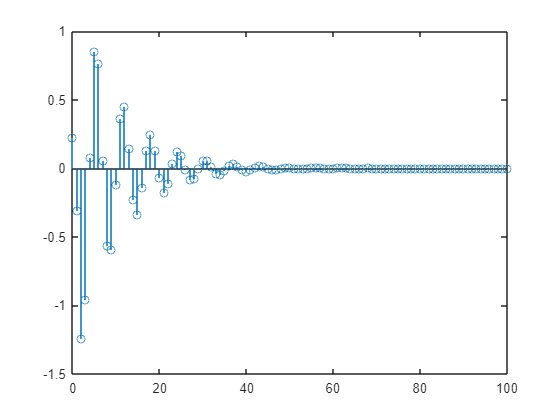

imp_7 = conv(num7, 1 ./ den7);
conv_7 = conv(x, imp_7, 'same');
stem(n,conv_7)

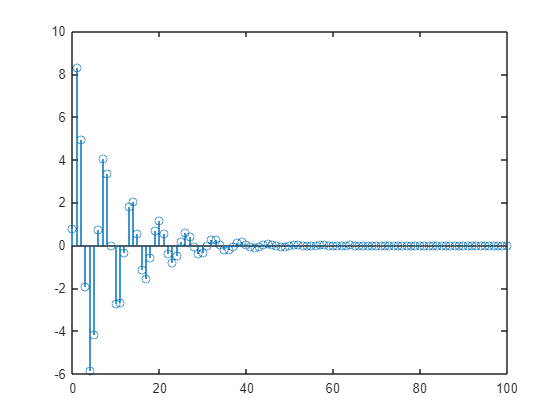

imp_8 = conv(1, 1 ./ den8);
conv_8 = conv(x, imp_8, 'same');
stem(n,conv_8)

## **TASK 2 (e)**

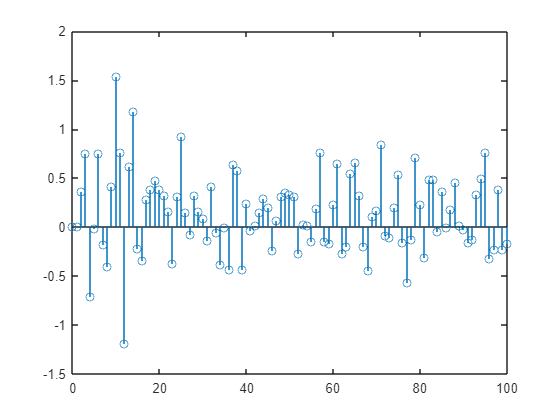

noise = normrnd(0.2, 0.3, size(n));

filt1 = filter(num1, den1, noise);
stem(n,filt1)

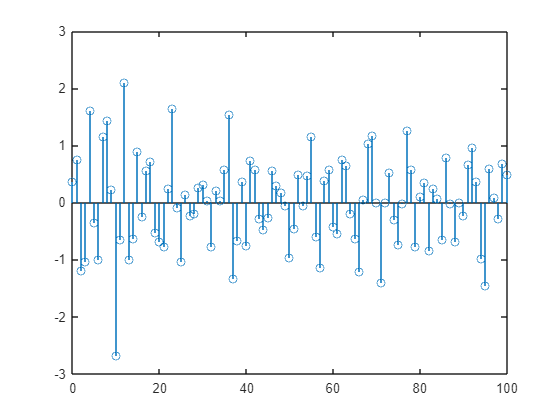

filt2 = filter(num2, den2, noise);
stem(n,filt2)

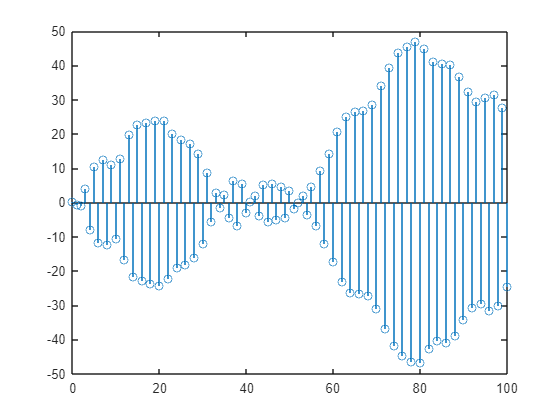

filt3 = filter(num3, den3, noise);
stem(n,filt3)

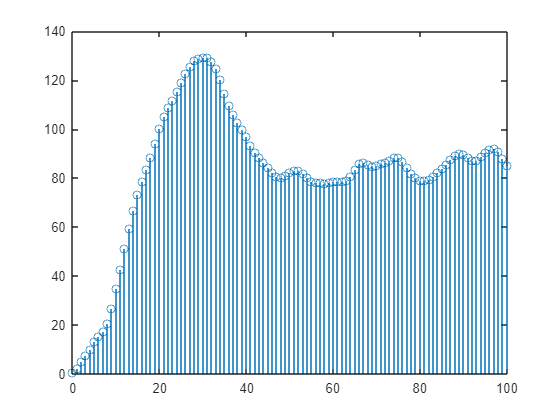

filt4 = filter(num4, den4, noise);
stem(n,filt4)

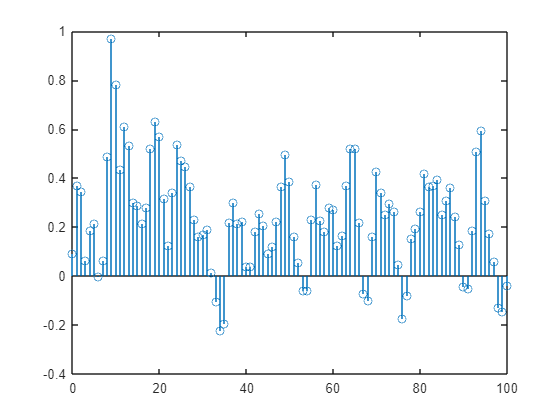

filt5 = filter(num5, 1, noise);
stem(n,filt5)

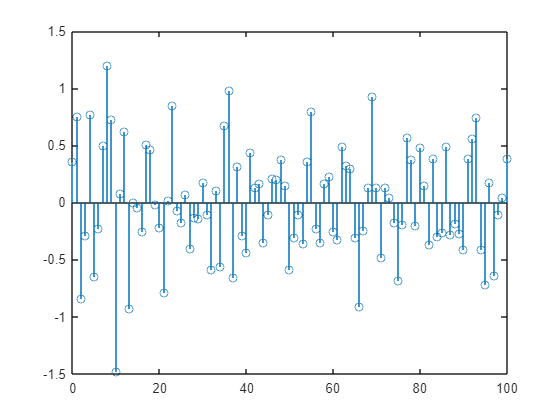

filt6 = filter(num6, 1, noise);
stem(n,filt6)

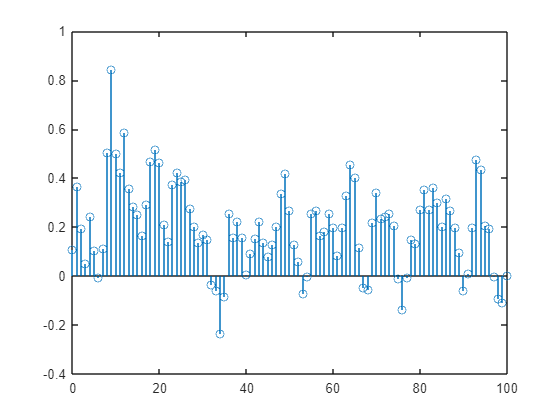

filt7 = filter(num7, den7, noise);
stem(n,filt7)

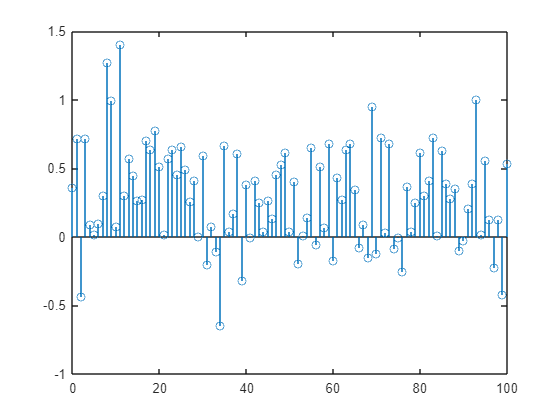

filt8 = filter(1, den8, noise);
stem(n,filt8)

## **TASK 3 (a)**

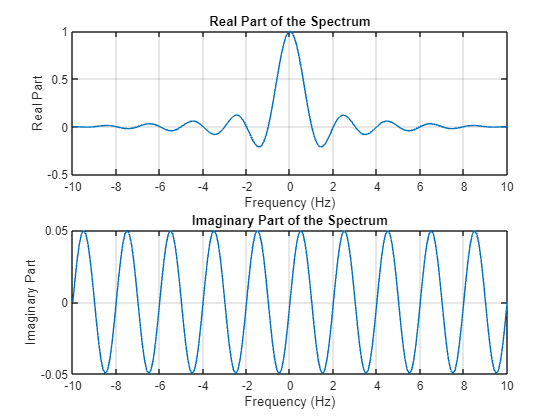

T=1; F_s = 20; T_s = 1/F_s; 
t_s = -T/2:T_s:T/2;
freqs = -10:0.1:10;
omega = 2*pi*freqs;
f_t = @(t) rectpuls(t / T);
f_sampled = f_t(t_s);

spectrum = zeros(size(omega));
for m = 1:length(t_s)
    spectrum = spectrum + f_sampled(m) * exp(-1j * omega * t_s(m)) * T_s;
end

figure;
subplot(2,1,1);
plot(freqs, real(spectrum));
xlabel('Frequency (Hz)');
ylabel('Real Part');
title('Real Part of the Spectrum');
grid on;

subplot(2,1,2);
plot(freqs, imag(spectrum));
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');
title('Imaginary Part of the Spectrum');
grid on;

## **TASK 3 (b)**

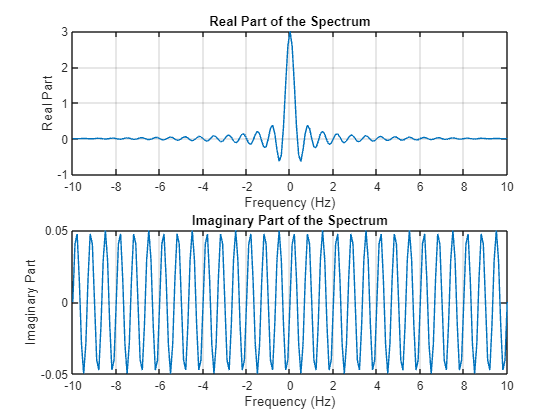

T_2 = 3; t_s2 = -T_2/2:T_s:T_2/2;

f_t2 = @(t) rectpuls(t / T_2);
f_sampled2 = f_t2(t_s2);

spectrum_2 = zeros(size(omega));
for m = 1:length(t_s2)
    spectrum_2 = spectrum_2 + f_sampled2(m) * exp(-1j * omega * t_s2(m)) * T_s;
end

figure;
subplot(2,1,1);
plot(freqs, real(spectrum_2));
xlabel('Frequency (Hz)');
ylabel('Real Part');
title('Real Part of the Spectrum');
grid on;

subplot(2,1,2);
plot(freqs, imag(spectrum_2));
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');
title('Imaginary Part of the Spectrum');
grid on;

## **TASK 3 (c)**

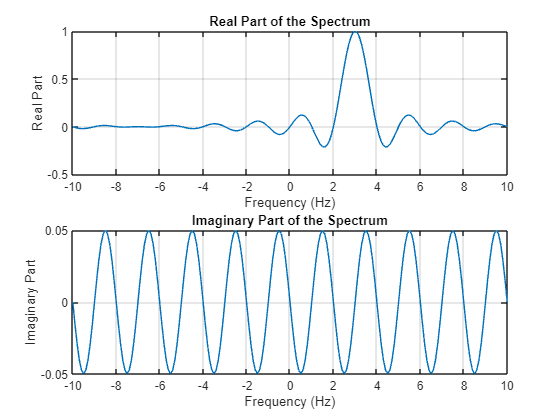

f_c = 3;
g_t = f_sampled .* exp(1j * 2 * pi * f_c * t_s);

spectrum_c = zeros(size(omega));
for m = 1:length(t_s)
    spectrum_c = spectrum_c + g_t(m) * exp(-1j * omega * t_s(m)) * T_s;
end

figure;
subplot(2,1,1);
plot(freqs, real(spectrum_c));
xlabel('Frequency (Hz)');
ylabel('Real Part');
title('Real Part of the Spectrum');
grid on;

subplot(2,1,2);
plot(freqs, imag(spectrum_c));
xlabel('Frequency (Hz)');
ylabel('Imaginary Part');
title('Imaginary Part of the Spectrum');
grid on;